# Practice 5 

# Comparison Risk Parity, Markowitz, and Equally Weighted 

To get the 50-50 case, or others cases (x), change variable prop at line 66 with "prop=0.x".

Weights are called wEW, wMV, wRP and wHRP.

X = EW, MV, RP, HRP

Average returns are called ret_in_X and ret_out_X  

Volatility is called risk_in_X and risk_out_X

Sharpe ratios are Sharpe_in_X and Sharpe_out_X

If "in" is contained in a variable name, means it refers to the in sample, while "out" refers to the out of sample.

As performance measure, except those already cited, when considering EW as benchmark, we found Beta, Treynor's Ratio, Jensen's Alpha, Max Drawdown and we tried to do Sortino but had a problem (last section).

At the end of the code there are some recap tables with all the values and significance tests on them.

# Your name:

**Miguel Ángel González Álvarez**

**Emilly Noelia Villacís Recalde**

**Quinten Woumans**

**Stokely Blake Ross**

**Edoardo Anfelli**

This version: 21/09/2024

### Grading: 4 points

You work as a financial consultant, and your client is a well-known pension fund named PF. PF wants to create a portfolio by investing in several individual stocks in the DJIA, taking long-only positions. They have asked you to recommend the optimal portfolio choice and suggested you try the Markowitz and Risk Parity approaches to build it. 

You have agreed to use daily data for your study available in dowPortfolio.xlsx. PF is aware of the shortcomings of traditional approaches, such as Markowitz, for building optimal portfolios. They have asked you to split the sample into two sub-samples. The first sub-sample, the in-sample or training data, should include 30% of the whole sample and be used to estimate optimal portfolio weights and choose the portfolio structure. The second sub-sample, the out-of-sample or testing data, should include the remaining 70% of the complete database and be used to test whether the portfolio performance behaves as it did in the training data by comparing EW, Markowitz and Risk Parity.Therefore, you should apply the training sample weights when computing the out-of-sample portfolios' performance measures.

PF representatives have suggested using a simple, equally weighted (EW) portfolio as the benchmark to compare the performance of other, more sophisticated portfolios such as Markowitz and Risk Parity. You should present a report with your conclusions and recommendations and use the performance measures you see fit to give your client a proper assessment of the situation. The monthly implementation cost of each strategy as a percentage of the invested amount is 0.5%, 0.6%, and 0.01% for Markowitz, Risk Parity, and EW (equally-weighted) strategies, respectively.

# Write your answer here

To assess the robustness of the Markowitz mean-variance, Equal Weights, and both simple and hierarchical Risk Parity asset allocation methods, the excess returns of the Dow Jones Industrial Average in 2006—calculated from closing prices and using the 3-month U.S. Treasury Bill yield as the risk-free rate—were divided into two samples: a training sample and a testing sample.

Firstly, the training sample used included the excess returns of the first 30% of trading days in 2006, while the testing sample included the remaining 70%. 

**MARKOVITZ**

In this scenario, the optimal portfolio using the Markowitz mean-variance method was constructed for the training sample, maximizing the Sharpe Ratio by considering the expected returns of the 30 stocks while accounting for the costs of using a Markowitz portfolio (0.5% monthly) and the risk-free asset, as well as the covariances between them. The Sharpe Ratio of the optimal portfolio in the training sample was approximately 0.31. However, when the optimal weights from the training sample were applied to the testing sample, the portfolio's Sharpe Ratio dropped to around -0.02, highlighting the poor robustness of the Markowitz asset allocation method.

**EQUALLY WEIGHTED**

Two additional portfolio models were created for the training and testing samples, with returns adjusted for the costs of using an Equally Weighted portfolio (0.01% monthly) and considering the covariances among the DJIA stocks. A weight of 1/31 was assigned to each stock (30 stocks plus the 3-month Treasury Bill), resulting in a Sharpe Ratio of 0.098 for the in-sample portfolio. When the same weights were applied to the out-of-sample portfolio, a similar Sharpe Ratio of 0.06 was achieved.

The EW, thanks to its balanced approach to assets’ weights, was the best if we talk about Maximum Drawdowns in the testing dataset..

**RISK PARITY**

The same procedure was used to create two additional portfolio models, accounting for the costs of using the Risk Parity strategy (0.6% monthly). With the **Simple **Risk Parity asset allocation, the Sharpe Ratio of the in-sample portfolio was approximately 0.026. However, when applying these weights to the out-of-sample portfolio, the Sharpe Ratio increased to 0.059, despite the considerable costs of the Risk Parity strategy. A similar outcome occurred with the **Hierarchical **Risk Parity strategy, where the in-sample Sharpe Ratio was around 0.021, and the out-of-sample Sharpe Ratio improved to 0.074 with the same weights.

In the second scenario, the training sample consisted of the excess returns from the first 50% of trading days in 2006, while the testing sample included the remaining half. For all four methods, when using a 50-50 split, the Sharpe Ratios were lower compared to the portfolios in Scenario 1 (which used a 30-70 split). In fact, the in-sample Sharpe Ratios for both the Simple and Hierarchical Risk Parity strategies were negative, but became significantly positive out-of-sample. The Equally Weighted portfolio also saw a notable increase in its Sharpe Ratio, rising by approximately 6% from in-sample to out-of-sample. The Markowitz portfolio behaved similarly to Scenario 1, though with lower Sharpe Ratios for both in-sample and out-of-sample cases.

Overall, there was insufficient statistical evidence to confirm that any of the Sharpe Ratios were significantly different from 0. However, given that daily returns have been used, which are typically very small, this result is understandable because near 0.

Additionally, when considering the Equally Weighted portfolio as the market portfolio (the benchmark), Jensen’s alpha followed a similar pattern to the Sharpe Ratio, moving consistently from in-sample to out-of-sample portfolios, in particular good improvement there has been for the hierarchical risk parity (Alphas are all significant), meanwhile Markovitz showed poor robustness when talking about beating the market, in fact became negative.

Treynor’s ratio in Markovitz, drops drastically when using the testing dataset, compared to risk parity which kept stable/showed small improvements.

**In conclusion**, the Risk Parity portfolio is the recommended choice due to its consistently strongly robust performance across various metrics. For more conservative investors, the Equally Weighted portfolio is a viable option, offering lower but steadier performance and significantly lower costs. The Markowitz portfolio is not recommended, given its poor and volatile performance.

# Do not write in this section

Read a table of daily adjusted close stock prices for the components of and the DJIA index.

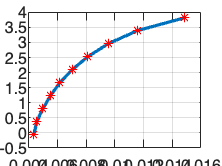


clear all
T = readtable('dowPortfolio.xlsx');
Names=T.Properties.VariableNames;
% Show data
Tx = T(:,Names);
plot(Tx.Dates,Tx.DJI)
title('Dow Jones Index Daily stock price 2006')


marketData=Tx(:,2:end)

marketData = 251×31 table
     DJI      AA       AIG      AXP      BA        C       CAT      DD       DIS      GE       GM       HD       HON      HPQ      IBM     INTC      JNJ      JPM      KO       MCD      MMM      MO       MRK     MSFT      PFE      PG        T       UTX      VZ       WMT      XOM 
    _____    _____    _____    _____    _____    _____    

pricesTTx = table2timetable(Tx)

pricesTTx = 251×31 timetable
       Dates        DJI      AA       AIG      AXP      BA        C       CAT      DD       DIS      GE       GM       HD       HON      HPQ      IBM     INTC      JNJ      JPM      KO       MCD      MMM      MO       MRK     MSFT      PFE      PG        T       UTX      VZ       WMT      XOM 
    ___________    _____    _____    _____    _____

marketData=pricesTTx.Variables;
normalizedPrice = (marketData - mean(marketData))./std(marketData);
normalizedPrice = normalizedPrice - normalizedPrice(1,:);
plot(pricesTTx.Dates,normalizedPrice);
Symbols=Names(2:end)

Symbols = 1×31 cell array
    {'DJI'}    {'AA'}    {'AIG'}    {'AXP'}    {'BA'}    {'C'}    {'CAT'}    {'DD'}    {'DIS'}    {'GE'}    {'GM'}    {'HD'}    {'HON'}    {'HPQ'}    {'IBM'}    {'INTC'}    {'JNJ'}    {'JPM'}    {'KO'}    {'MCD'}    {'MMM'}    {'MO'}    {'MRK'}    {'MSFT'}    {'PFE'}    {'PG'}    {'T'}    {'UTX'}    {'VZ'}    {'WMT'}    {'XOM'}


legend(Symbols, 'interpreter', 'none', 'Location', 'bestoutside')


% Risk-free rate from FRED
url = 'https://fred.stlouisfed.org/';

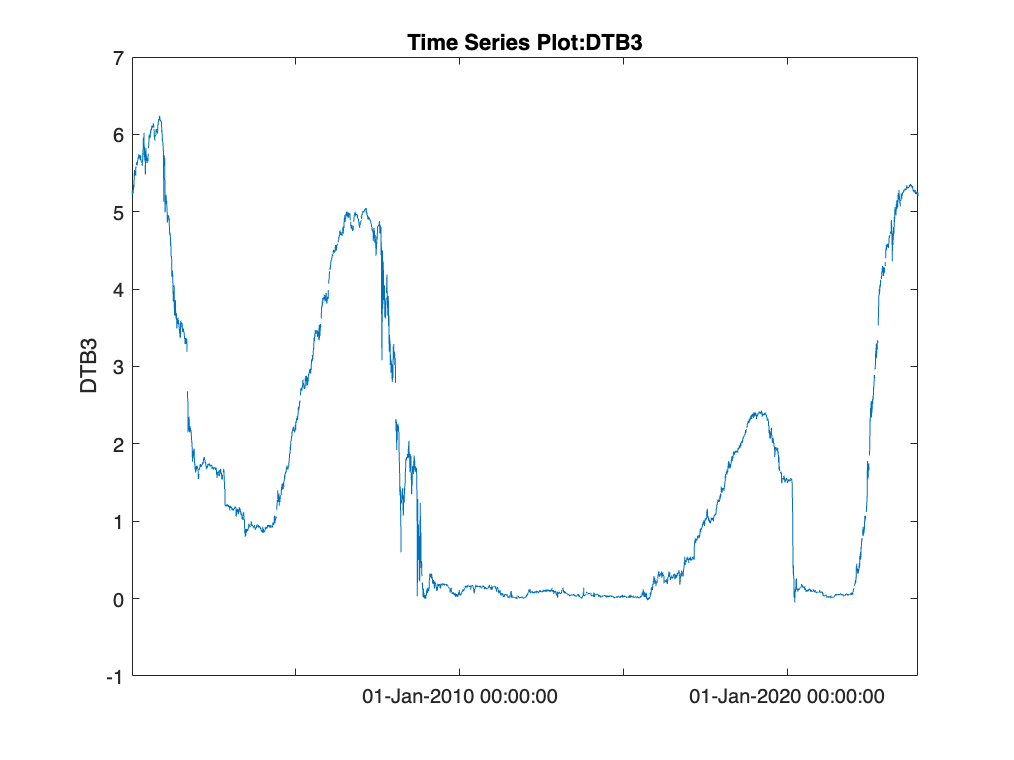

c = fred(url);
format bank
%3-Month Treasury Bill Secondary Market Rate, Discount Basis (DTB3)
% Daily data. Yields in percent per annum
% Date format Month/Day/Year
series = 'DTB3'; 
startdate = '01/03/2000'; % beginning of date range for historical data
enddate = '12/30/2023'; % ending of date range for historical data
d3m = fetch(c,series,startdate,enddate);
dts3m = timeseries([d3m.Data(:,2)], datestr(d3m.Data(:,1)));
dts3m.Name = series;
plot(dts3m);

% Data presents missing values
TT3m = timeseries2timetable(dts3m);
TT3m=fillmissing(TT3m,'pchip');
%plot(TT3m.Time, TT3m.DTB3)
%tscombX = timeseries(marketData)
%tscombX.TimeInfo = pricesTTx.Dates 
%TmarketData=timeseries2timetable(tscombX);

% Synchronize stock market and interest rate data
TTSS=synchronize(pricesTTx,TT3m,'intersection');

% Define risk-free rate 
format short
r_tb_3m=(TTSS.DTB3/100)/365 ;

% Compute excess returns full sample
Returns=price2ret(marketData,Method="periodic") - r_tb_3m(2:end);
samplesize=length(Returns);

assets=TTSS.Properties.VariableNames;
assets=assets(:,2:end)

assets = 1×31 cell array
    {'AA'}    {'AIG'}    {'AXP'}    {'BA'}    {'C'}    {'CAT'}    {'DD'}    {'DIS'}    {'GE'}    {'GM'}    {'HD'}    {'HON'}    {'HPQ'}    {'IBM'}    {'INTC'}    {'JNJ'}    {'JPM'}    {'KO'}    {'MCD'}    {'MMM'}    {'MO'}    {'MRK'}    {'MSFT'}    {'PFE'}    {'PG'}    {'T'}    {'UTX'}    {'VZ'}    {'WMT'}    {'XOM'}    {'DTB3'}


COSTS 

% Define monthly implementation costs (as percentages)
cost_in_EW = 0.01 / 100;    % 0.01% monthly for EW
cost_in_MV = 0.5 / 100;     % 0.5% monthly for MV
cost_in_HRP = 0.6 / 100;    % 0.6% monthly for HRP
cost_in_SimpleRP = 0.4 / 100;  % 0.4% monthly for Simple RP (assumed)

% Approximate number of trading days in a month
days_per_month = 21;

% Compute excess returns in-sample  (k% full sample)

prop=0.3;

returnsx_in = Returns(1:round(prop*samplesize),:);
m_inMV = mean(returnsx_in) - (cost_in_MV / days_per_month);
m_inEW = mean(returnsx_in) - (cost_in_EW / days_per_month);
m_inRP = mean(returnsx_in) - (cost_in_HRP / days_per_month);

C_in = cov(returnsx_in);

% Compute excess returns out-of-sample  
returnsx_out = Returns(round(prop*samplesize)+1:end,:);
m_outMV=mean(returnsx_out) - (cost_in_MV / days_per_month);
m_outEW=mean(returnsx_out) - (cost_in_EW / days_per_month);
m_outRP=mean(returnsx_out) - (cost_in_HRP / days_per_month);

C_out = cov(returnsx_out);


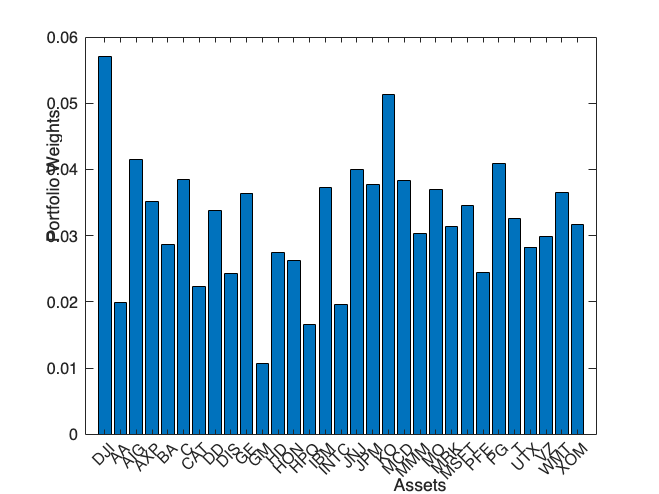

% In-sample Markowitz portfolio
pM = Portfolio;
pM = Portfolio(pM, 'LowerBound', zeros(size(m_inMV))); % Do Not Allow short positions
pM = Portfolio(pM, 'LowerBudget', 1, 'UpperBudget', 1);
pM = Portfolio(pM, 'AssetMean', m_inMV, 'AssetCovar', C_in);
plotFrontier(pM);
numport=10;
pwgtM = estimateFrontier(pM, numport);
[stdFM, retFM] = estimatePortMoments(pM, pwgtM);  % mean and std


wMV = estimateMaxSharpeRatio(pM)

wMV =     0.0000
    0.0000
    0.0000
    0.0000
    0.3157
    0.0000
    0.3855
    0.0000
    0.1325
    0.0000


[risk_in_MV, ret_in_MV] = estimatePortMoments(pM, wMV)

risk_in_MV = 0.0086

ret_in_MV = 0.0027

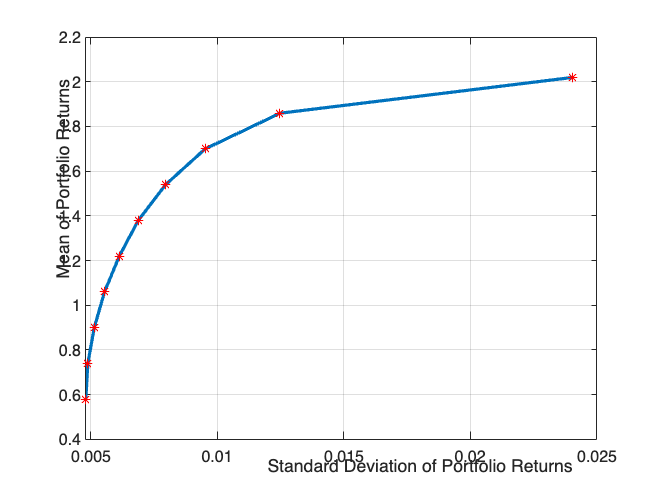

% Out-of-sample Markowitz portfolio
pMO = Portfolio;
pMO = Portfolio(pMO, 'LowerBound', zeros(size(m_outMV))); % Do Not Allow short positions
pMO = Portfolio(pMO, 'LowerBudget', 1, 'UpperBudget', 1);
pMO = Portfolio(pMO, 'AssetMean', m_outMV, 'AssetCovar', C_out);
plotFrontier(pMO);
numport=10;
pwgtMO = estimateFrontier(pMO, numport);
[stdFMO, retFMO] = estimatePortMoments(pMO, pwgtMO);  % mean and std
hold on
plot(stdFMO,retFMO,'*r');
hold off 


[risk_out_MV, ret_out_MV] = estimatePortMoments(pMO, wMV)

risk_out_MV = 0.0117

ret_out_MV = -2.6477e-04

% In-sample EW portfolio
pEW = Portfolio;
pEW = Portfolio(pEW, 'LowerBound', zeros(size(m_inEW))); % Do Not Allow short positions
pEW = Portfolio(pEW, 'LowerBudget', 1, 'UpperBudget', 1);
pEW = Portfolio(pEW, 'AssetMean', m_inEW, 'AssetCovar', C_in);

nassets=length(m_inEW);
% Equal weights to all assets
wEW=((1/nassets)*(ones(nassets, 1)));

[risk_in_EW, ret_in_EW] = estimatePortMoments(pEW, wEW)  % mean and std

risk_in_EW = 0.0060

ret_in_EW = 5.8944e-04

% Out-of-sample EW portfolio
pEWO = Portfolio;
pEWO = Portfolio(pEWO, 'LowerBound', zeros(size(m_outEW))); % Do Not Allow short positions
pEWO = Portfolio(pEWO, 'LowerBudget', 1, 'UpperBudget', 1);
pEWO = Portfolio(pEWO, 'AssetMean', m_outEW, 'AssetCovar', C_out);

[risk_out_EW, ret_out_EW] = estimatePortMoments(pMO, wEW)  % mean and std

risk_out_EW = 0.0065

ret_out_EW = 4.0660e-04

In-sample Simple Risk Parity

% In-sample Simple Risk Parity portfolio (Inverse Volatility weights)
std_returnsx_in = std(returnsx_in);  % 1 x nAssets row vector

% Simple Risk Parity weights (Inverse Volatility)
wRP = 1 ./ std_returnsx_in;   % 1 x nAssets row vector
wRP = wRP / sum(wRP);  % Normalize to sum to 1
wRP = wRP';  % Convert to column vector of size nAssets x 1

% In-sample RP portfolio
pRP = Portfolio;
pRP = Portfolio(pRP, 'LowerBound', zeros(size(m_inRP))); % Do Not Allow short positions
pRP = Portfolio(pRP, 'LowerBudget', 1, 'UpperBudget', 1);
pRP = Portfolio(pRP, 'AssetMean', m_inRP, 'AssetCovar', C_in);

% Compute in-sample performance for the Simple RP portfolio
[risk_in_SimpleRP, ret_in_SimpleRP] = estimatePortMoments(pRP, wRP)

risk_in_SimpleRP = 0.0057

ret_in_SimpleRP = 1.5191e-04

Out-of-sample Simple Risk Parity

% In-sample Simple Risk Parity portfolio (Inverse Volatility weights)

% In-sample RP portfolio
pRPO = Portfolio;
pRPO = Portfolio(pRPO, 'LowerBound', zeros(size(m_outRP))); % Do Not Allow short positions
pRPO = Portfolio(pRPO, 'LowerBudget', 1, 'UpperBudget', 1);
pRPO = Portfolio(pRPO, 'AssetMean', m_outRP, 'AssetCovar', C_out);

% Compute in-sample performance for the Simple RP portfolio
[risk_out_SimpleRP, ret_out_SimpleRP] = estimatePortMoments(pRPO, wRP)

risk_out_SimpleRP = 0.0062

ret_out_SimpleRP = 3.6932e-04

RP Hierarchical

% In-sample H Risk Parity portfolio
%heatmap(C);
mean_returnsx_1=m_inRP;
std_returnsx_1=std(returnsx_in);
Sigmax =C_in;
Cx = corrcov(Sigmax);

% Calculate weights of the risk parity portfolio by clustering by correlations
% Compute the correlation distance matrix
distCorr = ((1-Cx)/2).^0.5;
% Compute the linkage
link = linkage(distCorr);
% Sort assets for quasi-diagonalization 
nLeafNodes = size(link,1) + 1;
rootNodeId = 2*nLeafNodes - 1;
sortedIdx = getLeafNodesInGroup(rootNodeId,link);

% Get clusters
Tx = cluster(link, MaxClust=6);
% Assets in each cluster (asset 5 is in cluster 2 and so on)

% Compute RP portfolio
wHRP = hrpPortfolio(Tx,Sigmax);
% Weights Risk Parity Portfolio
bar(wHRP)
title('Risk Parity weights')
[risk_in_RP, ret_in_RP] = estimatePortMoments(pRP, wHRP)

risk_in_RP = 0.0061

ret_in_RP = 1.3033e-04

% Out-of-sample H Risk Parity portfolio
[risk_out_RP, ret_out_RP] = estimatePortMoments(pRPO, wHRP)

risk_out_RP = 0.0081

ret_out_RP = 6.0440e-04

% Create a table with all weights
weights_table = table(assets', wEW, wMV, wRP, wHRP)

weights_table = 31×5 table
      Var1        wEW          wMV          wRP         wHRP   
    ________    ________    __________    ________    _________

    {'AA'  }    0.032258    3.2667e-17    0.057109     0.010422
    {'AIG' }    0.032258    8.0712e-13    0.019867    0.0090624
    {'AXP' }    0.032258     1.785e-17    0.041518     0.010549
    {'BA'  }    0.032258    2.3365e-17    0.035171    0.0098089
    {'C'   }    0.032258       0.31567    0.028652    0.0094516
    {'CAT' }    0.032258    2.5828e-17    0.038415     0.011223
    {'DD'  }    0.032258       0.38554    0.022347    0.0060865
    {'DIS' }    0.032258    5.5111e-17    0.033809     0.012424
    {'GE'  }    0.032258       0.13248    0.024279      0.15506
    {'GM'  }    0.032258    2.0952e-17    0.036424    0.0096859
    {'HD'  }    0.032258      0.06

    'VariableNames', {'Asset', 'EW_Weights', 'MV_Weights', 'RP_Weights', 'HRP_Weights'};

ans = 'VariableNames'


% Display the table
disp(weights_table);

      Var1        wEW          wMV          wRP         wHRP   
    ________    ________    __________    ________    _________

    {'AA'  }    0.032258    3.2667e-17    0.057109     0.010422
    {'AIG' }    0.032258    8.0712e-13    0.019867    0.0090624
    {'AXP' }    0.032258     1.785e-17    0.041518     0.010549
    {'BA'  }    0.032258    2.3365e-17    0.035171    0.0098089
    {'C'   }    0.032258       0.31567    0.028652    0.0094516
    {'CAT' }    0.032258    2.5828e-17    0.038415     0.011223
    {'DD'  }    0.032258       0.38554    0.022347    0.0060865
    {'DIS' }    0.032258    5.5111e-17    0.033809     0.012424
    {'GE'  }    0.032258       0.13248    0.024279      0.15506
    {'GM'  }    0.032258    2.0952e-17    0.036424    0.0096859
    {'HD'  }    0.032258      0.069666    0.010698     0.0650

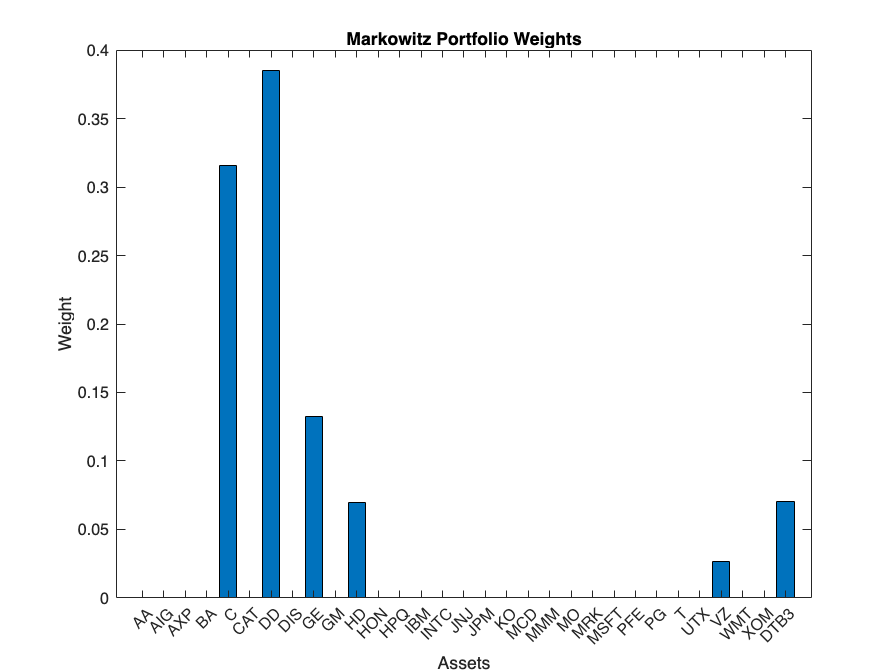


% Bar graph for Equally Weighted portfolio
figure('Visible','on')
hold on
bar(wEW);
title('Equally Weighted Portfolio Weights');
xlabel('Assets');
ylabel('Weight');
set(gca, 'XTickLabel', assets, 'XTick', 1:numel(assets));
xtickangle(45);

% Bar graph for Markowitz (MV) portfolio
figure;
bar(wMV);
title('Markowitz Portfolio Weights');
xlabel('Assets');
ylabel('Weight');
set(gca, 'XTickLabel', assets, 'XTick', 1:numel(assets));
xtickangle(45);

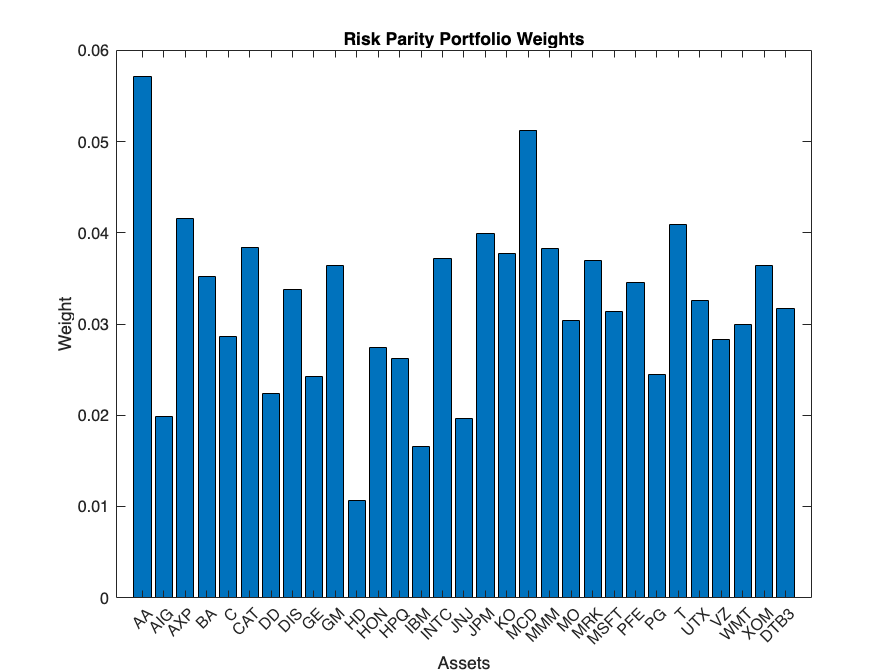


% Bar graph for Risk Parity (RP) portfolio
figure;
bar(wRP);
title('Risk Parity Portfolio Weights');
xlabel('Assets');
ylabel('Weight');
set(gca, 'XTickLabel', assets, 'XTick', 1:numel(assets));
xtickangle(45);

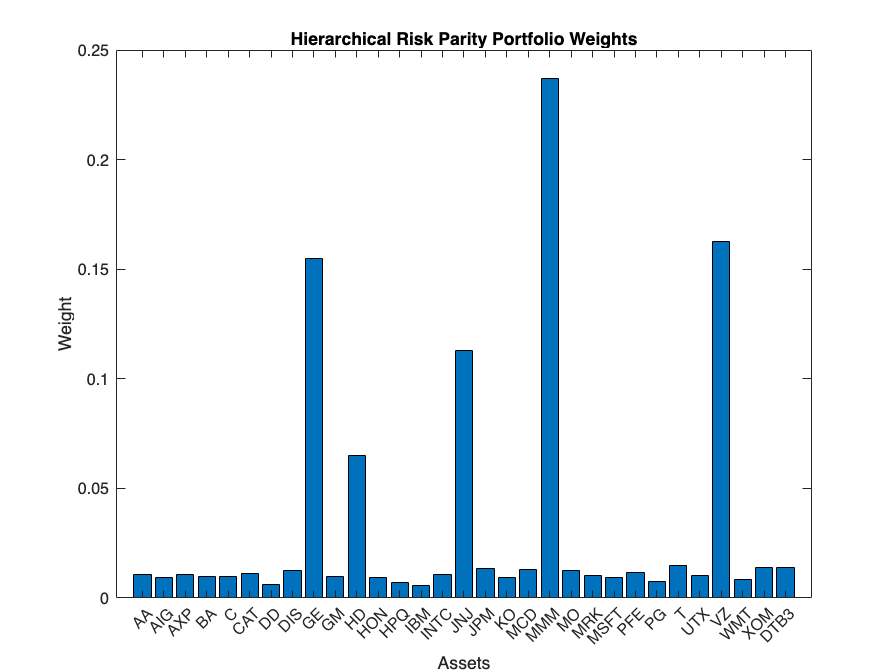


% Bar graph for Hierarchical Risk Parity (HRP) portfolio
figure;
bar(wHRP);
title('Hierarchical Risk Parity Portfolio Weights');
xlabel('Assets');
ylabel('Weight');
set(gca, 'XTickLabel', assets, 'XTick', 1:numel(assets));
xtickangle(45);
hold off

performance analysis

%compute average returns of assets in each portfolio by multiplying weights with average return (m) of that
%specific asset (from which has been already removed costs)
returnsinMV=wMV.*m_inMV'

returnsinMV =     0.0000
    0.0000
   -0.0000
   -0.0000
    0.0008
   -0.0000
    0.0015
    0.0000
    0.0001
   -0.0000


returnsoutMV=wMV.*m_outMV'

returnsoutMV = 1.0e-03 *

    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0118
    0.0000
   -0.5804
    0.0000
    0.1462
    0.0000


returnsinEW=wEW.*m_inEW'

returnsinEW = 1.0e-03 *

    0.0159
    0.0751
   -0.0395
   -0.0034
    0.0882
   -0.0096
    0.1310
    0.0167
    0.0428
   -0.0168


returnsoutEW=wEW.*m_outEW'

returnsoutEW = 1.0e-04 *

    0.1349
   -0.2723
    0.1945
    0.2573
    0.0632
    0.2986
   -0.4104
    0.1819
    0.4313
    0.1723


returnsinRP=wRP.*m_inRP'

returnsinRP = 1.0e-04 *

    0.1202
    0.4064
   -0.6249
   -0.1360
    0.7025
   -0.2219
    0.8446
    0.0801
    0.2540
   -0.2919


returnsoutRP=wRP.*m_outRP'

returnsoutRP = 1.0e-04 *

    0.0784
   -0.2235
    0.1337
    0.1817
   -0.0243
    0.2477
   -0.3471
    0.0957
    0.2564
    0.0922


returnsinHRP=wHRP.*m_inRP'

returnsinHRP = 1.0e-03 *

    0.0022
    0.0185
   -0.0159
   -0.0038
    0.0232
   -0.0065
    0.0230
    0.0029
    0.1622
   -0.0078


returnsoutHRP=wHRP.*m_outRP'

returnsoutHRP = 1.0e-03 *

    0.0014
   -0.0102
    0.0034
    0.0051
   -0.0008
    0.0072
   -0.0095
    0.0035
    0.1637
    0.0025




% Sharpe Ratio Calculation
% Sharpe Ratios for in-sample and out-sample
Sharpe_in_HRP = (ret_in_RP) / risk_in_RP;
Sharpe_out_HRP = (ret_out_RP) / risk_out_RP;
Sharpe_in_RP = (ret_in_SimpleRP) / risk_in_SimpleRP;
Sharpe_out_RP = (ret_out_SimpleRP) / risk_out_SimpleRP;

Sharpe_EW_in = (ret_in_EW) / risk_in_EW;
Sharpe_EW_out = (ret_out_EW) / risk_out_EW;

Sharpe_MV_in = (ret_in_MV) / risk_in_MV;
Sharpe_MV_out = (ret_out_MV) / risk_out_MV;

% T-test for Sharpe Ratio
n_in = 75;  
n_out = 175; 

% T-statistics for in-sample and out-sample
t_Sharpe_in_HRP = Sharpe_in_HRP * sqrt(n_in);
t_Sharpe_out_HRP = Sharpe_out_HRP * sqrt(n_out);
t_Sharpe_in_RP = Sharpe_in_RP * sqrt(n_in);  % For Simple RP
t_Sharpe_out_RP = Sharpe_out_RP * sqrt(n_out);  % For Simple RP

t_Sharpe_EW_in = Sharpe_EW_in * sqrt(n_in);
t_Sharpe_EW_out = Sharpe_EW_out * sqrt(n_out);

t_Sharpe_MV_in = Sharpe_MV_in * sqrt(n_in);  % Assuming in MV for optimal
t_Sharpe_MV_out = Sharpe_MV_out * sqrt(n_out);  % Assuming out MV for optimal

% P-value calculation
p_value_in_RP = 2 * (1 - tcdf(abs(t_Sharpe_in_HRP), n_in - 1));
p_value_out_RP = 2 * (1 - tcdf(abs(t_Sharpe_out_HRP), n_out - 1));
p_value_in_SimpleRP = 2 * (1 - tcdf(abs(t_Sharpe_in_RP), n_in - 1));
p_value_out_SimpleRP = 2 * (1 - tcdf(abs(t_Sharpe_out_RP), n_out - 1));

p_value_EW_in = 2 * (1 - tcdf(abs(t_Sharpe_EW_in), n_in - 1));
p_value_EW_out = 2 * (1 - tcdf(abs(t_Sharpe_EW_out), n_out - 1));

p_value_MV_in = 2 * (1 - tcdf(abs(t_Sharpe_MV_in), n_in - 1));
p_value_MV_out = 2 * (1 - tcdf(abs(t_Sharpe_MV_out), n_out - 1));

% Display the Sharpe Ratios and p-values
disp('Sharpe Ratios and p-values:');

Sharpe Ratios and p-values:


disp(['Sharpe In RP: ', num2str(Sharpe_in_HRP), ' | p-value: ', num2str(p_value_in_RP)]);

Sharpe In RP: 0.021399 | p-value: 0.85348


disp(['Sharpe Out RP: ', num2str(Sharpe_out_HRP), ' | p-value: ', num2str(p_value_out_RP)]);

Sharpe Out RP: 0.074556 | p-value: 0.32536


disp(['Sharpe In SimpleRP: ', num2str(Sharpe_in_RP), ' | p-value: ', num2str(p_value_in_SimpleRP)]);

Sharpe In SimpleRP: 0.026766 | p-value: 0.81733


disp(['Sharpe Out SimpleRP: ', num2str(Sharpe_out_RP), ' | p-value: ', num2str(p_value_out_SimpleRP)]);

Sharpe Out SimpleRP: 0.05993 | p-value: 0.42897


disp(['Sharpe EW In: ', num2str(Sharpe_EW_in), ' | p-value: ', num2str(p_value_EW_in)]);

Sharpe EW In: 0.098679 | p-value: 0.39554


disp(['Sharpe EW Out: ', num2str(Sharpe_EW_out), ' | p-value: ', num2str(p_value_EW_out)]);

Sharpe EW Out: 0.06262 | p-value: 0.40858


disp(['Sharpe MV In: ', num2str(Sharpe_MV_in), ' | p-value: ', num2str(p_value_MV_in)]);

Sharpe MV In: 0.3127 | p-value: 0.0084007


disp(['Sharpe MV Out: ', num2str(Sharpe_MV_out), ' | p-value: ', num2str(p_value_MV_out)]);

Sharpe MV Out: -0.022574 | p-value: 0.76558


regress using eqwei as benchmark (market) and evaluate performances

m_rf=mean(r_tb_3m)

m_rf = 1.2960e-04

% In-sample regressions
% Regression 1: returnsinEW ~ returnsinMV
lm1_in = fitlm(returnsinMV, returnsinEW);
beta_in_MV = lm1_in.Coefficients.Estimate(2);  % Extract the beta (slope)
disp(['Beta (In-sample MV): ', num2str(beta_in_MV)]);

Beta (In-sample MV): 0.08991



% Regression 2: returnsinEW ~ returnsinRP
lm2_in = fitlm(returnsinRP, returnsinEW);
beta_in_RP = lm2_in.Coefficients.Estimate(2);
disp(['Beta (In-sample RP): ', num2str(beta_in_RP)]);

Beta (In-sample RP): 1.2316



% Regression 3: returnsinEW ~ returnsinHRP
lm3_in = fitlm(returnsinHRP, returnsinEW);
beta_in_HRP = lm3_in.Coefficients.Estimate(2);
disp(['Beta (In-sample HRP): ', num2str(beta_in_HRP)]);

Beta (In-sample HRP): 0.30472



% Out-of-sample regressions
% Regression 4: returnsoutEW ~ returnsoutMV
lm4_out = fitlm(returnsoutMV, returnsoutEW);
beta_out_MV = lm4_out.Coefficients.Estimate(2);
disp(['Beta (Out-of-sample MV): ', num2str(beta_out_MV)]);

Beta (Out-of-sample MV): 0.12509



% Regression 5: returnsoutEW ~ returnsoutRP
lm5_out = fitlm(returnsoutRP, returnsoutEW);
beta_out_RP = lm5_out.Coefficients.Estimate(2);
disp(['Beta (Out-of-sample RP): ', num2str(beta_out_RP)]);

Beta (Out-of-sample RP): 1.1022



% Regression 6: returnsoutEW ~ returnsoutHRP
lm6_out = fitlm(returnsoutHRP, returnsoutEW);
beta_out_HRP = lm6_out.Coefficients.Estimate(2);
disp(['Beta (Out-of-sample HRP): ', num2str(beta_out_HRP)]);

Beta (Out-of-sample HRP): 0.19234



% P-values for Betas (from the regression model)
p_value_beta_in_MV = lm1_in.Coefficients.pValue(2);
p_value_beta_in_RP = lm2_in.Coefficients.pValue(2);
p_value_beta_in_HRP = lm3_in.Coefficients.pValue(2);

p_value_beta_out_MV = lm4_out.Coefficients.pValue(2);
p_value_beta_out_RP = lm5_out.Coefficients.pValue(2);
p_value_beta_out_HRP = lm6_out.Coefficients.pValue(2);

% Treynor's Ratio In-Sample
Treynor_in_MV = ret_in_MV      / beta_in_MV;
Treynor_in_RP = ret_in_RP      / beta_in_RP;
Treynor_in_HRP =ret_in_HRP     / beta_in_HRP;

% Treynor's Ratio Out-of-Sample
Treynor_out_MV = ret_out_MV      / beta_out_MV;
Treynor_out_RP = ret_out_SimpleRP/ beta_out_RP;
Treynor_out_HRP =ret_out_RP       / beta_out_HRP;

% P-values for Treynor's Ratios
% Assuming we treat the Treynor's ratio as a t-statistic with degrees of freedom
t_stat_Treynor_in_MV = Treynor_in_MV / std(returnsinEW);
p_value_Treynor_in_MV = 2 * (1 - tcdf(abs(t_stat_Treynor_in_MV), length(returnsinEW) - 1));

t_stat_Treynor_in_RP = Treynor_in_RP / std(returnsinEW);
p_value_Treynor_in_RP = 2 * (1 - tcdf(abs(t_stat_Treynor_in_RP), length(returnsinEW) - 1));

t_stat_Treynor_in_HRP = Treynor_in_HRP / std(returnsinEW);
p_value_Treynor_in_HRP = 2 * (1 - tcdf(abs(t_stat_Treynor_in_HRP), length(returnsinEW) - 1));

t_stat_Treynor_out_MV = Treynor_out_MV / std(returnsoutEW);
p_value_Treynor_out_MV = 2 * (1 - tcdf(abs(t_stat_Treynor_out_MV), length(returnsoutEW) - 1));

t_stat_Treynor_out_RP = Treynor_out_RP / std(returnsoutEW);
p_value_Treynor_out_RP = 2 * (1 - tcdf(abs(t_stat_Treynor_out_RP), length(returnsoutEW) - 1));

t_stat_Treynor_out_HRP = Treynor_out_HRP / std(returnsoutEW);
p_value_Treynor_out_HRP = 2 * (1 - tcdf(abs(t_stat_Treynor_out_HRP), length(returnsoutEW) - 1));


% Display Treynor's Ratios
disp(['Treynor Ratio In-sample MV: ', num2str(Treynor_in_MV)]);

Treynor Ratio In-sample MV: 0.029821


disp(['Treynor Ratio In-sample RP: ', num2str(Treynor_in_RP)]);

Treynor Ratio In-sample RP: 0.00012335


disp(['Treynor Ratio In-sample HRP: ', num2str(Treynor_in_HRP)]);

Treynor Ratio In-sample HRP: 0.00042769



disp(['Treynor Ratio Out-of-sample MV: ', num2str(Treynor_out_MV)]);

Treynor Ratio Out-of-sample MV: -0.0021166


disp(['Treynor Ratio Out-of-sample RP: ', num2str(Treynor_out_RP)]);

Treynor Ratio Out-of-sample RP: 0.00033509


disp(['Treynor Ratio Out-of-sample HRP: ', num2str(Treynor_out_HRP)]);

Treynor Ratio Out-of-sample HRP: 0.0031424




% Jensen's Alpha In-Sample (Equally Weighted is the Market)
Jensen_in_MV =  ret_in_MV        + beta_in_MV  *  (ret_in_EW);
Jensen_in_RP =  ret_in_SimpleRP  + beta_in_RP  *  (ret_in_EW);
Jensen_in_HRP = ret_in_RP        + beta_in_HRP *  (ret_in_EW);

% Jensen's Alpha Out-of-Sample (Equally Weighted is the Mark
Jensen_out_MV =  ret_out_MV       - beta_out_MV *  (ret_out_EW);
Jensen_out_RP =  ret_out_SimpleRP - beta_out_RP *  (ret_out_EW);
Jensen_out_HRP = ret_out_RP       - beta_out_HRP * (ret_out_EW);

% Display Jensen's Alphas
disp(['Jensen Alpha In-sample MV: ', num2str(Jensen_in_MV)]);

Jensen Alpha In-sample MV: 0.0027341


disp(['Jensen Alpha In-sample RP: ', num2str(Jensen_in_RP)]);

Jensen Alpha In-sample RP: 0.00087787


disp(['Jensen Alpha In-sample HRP: ', num2str(Jensen_in_HRP)]);

Jensen Alpha In-sample HRP: 0.00030994



disp(['Jensen Alpha Out-of-sample MV: ', num2str(Jensen_out_MV)]);

Jensen Alpha Out-of-sample MV: -0.00031563


disp(['Jensen Alpha Out-of-sample RP: ', num2str(Jensen_out_RP)]);

Jensen Alpha Out-of-sample RP: -7.8818e-05


disp(['Jensen Alpha Out-of-sample HRP: ', num2str(Jensen_out_HRP)]);

Jensen Alpha Out-of-sample HRP: 0.00052619



% P-values for Jensen's Alpha (similar to p-values for Treynor's Ratio)
t_stat_Jensen_in_MV = Jensen_in_MV / std(returnsinEW);
p_value_Jensen_in_MV = 2 * (1 - tcdf(abs(t_stat_Jensen_in_MV), length(returnsinEW) - 1))

p_value_Jensen_in_MV = 0


t_stat_Jensen_in_RP = Jensen_in_RP / std(returnsinEW);
p_value_Jensen_in_RP = 2 * (1 - tcdf(abs(t_stat_Jensen_in_RP), length(returnsinEW) - 1))

p_value_Jensen_in_RP = 0


t_stat_Jensen_in_HRP = Jensen_in_HRP / std(returnsinEW);
p_value_Jensen_in_HRP = 2 * (1 - tcdf(abs(t_stat_Jensen_in_HRP), length(returnsinEW) - 1))

p_value_Jensen_in_HRP = 2.1731e-07


t_stat_Jensen_out_MV = Jensen_out_MV / std(returnsoutEW);
p_value_Jensen_out_MV = 2 * (1 - tcdf(abs(t_stat_Jensen_out_MV), length(returnsoutEW) - 1))

p_value_Jensen_out_MV = 5.4401e-14


t_stat_Jensen_out_RP = Jensen_out_RP / std(returnsoutEW);
p_value_Jensen_out_RP = 2 * (1 - tcdf(abs(t_stat_Jensen_out_RP), length(returnsoutEW) - 1))

p_value_Jensen_out_RP = 0.0026


t_stat_Jensen_out_HRP = Jensen_out_HRP / std(returnsoutEW);
p_value_Jensen_out_HRP = 2 * (1 - tcdf(abs(t_stat_Jensen_out_HRP), length(returnsoutEW) - 1))

p_value_Jensen_out_HRP = 0



% Cumulative returns calculation for each portfolio
cum_ret_in_MV = cumprod(1 + returnsinMV) - 1;
cum_ret_in_RP = cumprod(1 + returnsinRP) - 1;
cum_ret_in_HRP = cumprod(1 + returnsinHRP) - 1;
cum_ret_in_EW = cumprod(1 + returnsinEW) - 1;

cum_ret_out_MV = cumprod(1 + returnsoutMV) - 1;
cum_ret_out_RP = cumprod(1 + returnsoutRP) - 1;
cum_ret_out_HRP = cumprod(1 + returnsoutHRP) - 1;
cum_ret_out_EW = cumprod(1 + returnsoutEW) - 1;

% Maximum drawdown function
max_drawdown = @(cum_ret) min((cum_ret - cummax(cum_ret)) ./ cummax(cum_ret));

% In-sample Maximum Drawdown
MDD_in_MV = max_drawdown(cum_ret_in_MV);
MDD_in_RP = max_drawdown(cum_ret_in_RP);
MDD_in_HRP = max_drawdown(cum_ret_in_HRP);
MDD_in_EW = max_drawdown(cum_ret_in_EW);

% Out-of-sample Maximum Drawdown
MDD_out_MV = max_drawdown(cum_ret_out_MV);
MDD_out_RP = max_drawdown(cum_ret_out_RP);
MDD_out_HRP = max_drawdown(cum_ret_out_HRP);
MDD_out_EW = max_drawdown(cum_ret_out_EW);

% Display Maximum Drawdowns
disp('Maximum Drawdown In-sample:');

Maximum Drawdown In-sample:


disp(['MDD MV: ', num2str(MDD_in_MV)]);

MDD MV: 0


disp(['MDD RP: ', num2str(MDD_in_RP)]);

MDD RP: -1.4448


disp(['MDD HRP: ', num2str(MDD_in_HRP)]);

MDD HRP: -1.3752


disp(['MDD EW: ', num2str(MDD_in_EW)]);

MDD EW: -0.47195



disp('Maximum Drawdown Out-of-sample:');

Maximum Drawdown Out-of-sample:


disp(['MDD MV: ', num2str(MDD_out_MV)]);

MDD MV: -Inf


disp(['MDD RP: ', num2str(MDD_out_RP)]);

MDD RP: -2.8523


disp(['MDD HRP: ', num2str(MDD_out_HRP)]);

MDD HRP: -7.1293


disp(['MDD EW: ', num2str(MDD_out_EW)]);

MDD EW: -2.0189


RECAP TABLE

% Define portfolio names
portfolio_names = {'In-Sample MV', 'In-Sample RP', 'In-Sample HRP', 'In-Sample EW', ...
                   'Out-of-Sample MV', 'Out-of-Sample RP', 'Out-of-Sample HRP', 'Out-of-Sample EW'};

% Betas and Beta p-values
betas = [beta_in_MV, beta_in_RP, beta_in_HRP, 1, ...
         beta_out_MV, beta_out_RP, beta_out_HRP, 1];

beta_pvalues = [p_value_beta_in_MV, p_value_beta_in_RP, p_value_beta_in_HRP, NaN, ...
                p_value_beta_out_MV, p_value_beta_out_RP, p_value_beta_out_HRP, NaN];

% Treynor Ratios and Treynor p-values
treynor_ratios = [Treynor_in_MV, Treynor_in_RP, Treynor_in_HRP, NaN, ...
                  Treynor_out_MV, Treynor_out_RP, Treynor_out_HRP, NaN];

treynor_pvalues = [p_value_Treynor_in_MV, p_value_Treynor_in_RP, p_value_Treynor_in_HRP, NaN, ...
                   p_value_Treynor_out_MV, p_value_Treynor_out_RP, p_value_Treynor_out_HRP, NaN];

% Alphas (no p-values)
alphas = [Jensen_in_MV, Jensen_in_RP, Jensen_in_HRP, 0, ...
          Jensen_out_MV, Jensen_out_RP, Jensen_out_HRP, 0];

% Maximum Drawdowns (Max DDs)
max_dds = [MDD_in_MV, MDD_in_RP, MDD_in_HRP, MDD_in_EW, ...
           MDD_out_MV, MDD_out_RP, MDD_out_HRP, MDD_out_EW];

% Create the table
T = table(portfolio_names', betas', beta_pvalues', treynor_ratios', treynor_pvalues', ...
          alphas', max_dds', ...
          'VariableNames', {'Portfolio', 'Beta', 'Beta_pvalue', 'Treynor_Ratio', 'Treynor_pvalue', ...
                            'Alpha', 'Max_DD'});

% Display the table
disp(T);

          Portfolio           Beta      Beta_pvalue    Treynor_Ratio    Treynor_pvalue       Alpha        Max_DD 
    _____________________    _______    ___________    _____________    ______________    ___________    ________

    {'In-Sample MV'     }    0.08991    0.00077733        0.029821                 0        0.0027341           0
    {'In-Sample RP'     }     1.2316    2.6496e-17      0.00012335          0.012575       0.00087787     -1.4448
    {'In-Sample HRP'    }    0.30472    3.3399e-05      0.00042769        3.0339e-10       0.00030994     -1.3752
    {'In-Sample EW'     }          1           NaN             NaN               NaN                0    -0.47195
    {'Out-of-Sample MV' }    0.12509    0.00053686      -0.0021166           

% Define portfolio names
portfolio_names = {'In-Sample MV', 'In-Sample RP', 'In-Sample HRP', 'In-Sample EW', ...
                   'Out-of-Sample MV', 'Out-of-Sample RP', 'Out-of-Sample HRP', 'Out-of-Sample EW'};

% Collect Sharpe p-values
sharpe_pvalues = [p_value_MV_in, p_value_in_SimpleRP, p_value_in_RP, p_value_EW_in, ...
                  p_value_MV_out, p_value_out_SimpleRP, p_value_out_RP, p_value_EW_out];

% Collect Treynor p-values 
treynor_pvalues = [p_value_Treynor_in_MV, p_value_Treynor_in_RP, p_value_Treynor_in_HRP, NaN, ...
                   p_value_Treynor_out_MV, p_value_Treynor_out_RP, p_value_Treynor_out_HRP, NaN];

% Collect Beta p-values 
beta_pvalues = [p_value_beta_in_MV, p_value_beta_in_RP, p_value_beta_in_HRP, NaN, ...
                p_value_beta_out_MV, p_value_beta_out_RP, p_value_beta_out_HRP, NaN];

% Create the table
p_values_table = table(portfolio_names', sharpe_pvalues', treynor_pvalues', beta_pvalues', ...
    'VariableNames', {'Portfolio', 'Sharpe_pvalue', 'Treynor_pvalue', 'Beta_pvalue'});


% Define portfolio names for in-sample and out-of-sample
portfolio_names_in = {'In-Sample MV', 'In-Sample RP', 'In-Sample HRP', 'In-Sample EW'};
portfolio_names_out = {'Out-of-Sample MV', 'Out-of-Sample RP', 'Out-of-Sample HRP', 'Out-of-Sample EW'};

% In-sample significance threshold
threshold_in = 0.01;

% Out-of-sample significance threshold
threshold_out = 1/175;

% Collect in-sample p-values
sharpe_pvalues_in = [p_value_MV_in, p_value_in_SimpleRP, p_value_in_RP, p_value_EW_in];
treynor_pvalues_in = [p_value_Treynor_in_MV, p_value_Treynor_in_RP, p_value_Treynor_in_HRP, NaN];
beta_pvalues_in = [p_value_beta_in_MV, p_value_beta_in_RP, p_value_beta_in_HRP, NaN];

% Collect out-sample p-values
sharpe_pvalues_out = [p_value_MV_out, p_value_out_SimpleRP, p_value_out_RP, p_value_EW_out];
treynor_pvalues_out = [p_value_Treynor_out_MV, p_value_Treynor_out_RP, p_value_Treynor_out_HRP, NaN];
beta_pvalues_out = [p_value_beta_out_MV, p_value_beta_out_RP, p_value_beta_out_HRP, NaN];

% Check significance for in-sample
sharpe_significance_in = arrayfun(@(p) significance_check(p, threshold_in), sharpe_pvalues_in, 'UniformOutput', false);
treynor_significance_in = arrayfun(@(p) significance_check(p, threshold_in), treynor_pvalues_in, 'UniformOutput', false);
beta_significance_in = arrayfun(@(p) significance_check(p, threshold_in), beta_pvalues_in, 'UniformOutput', false);

% Check significance for out-sample
sharpe_significance_out = arrayfun(@(p) significance_check(p, threshold_out), sharpe_pvalues_out, 'UniformOutput', false);
treynor_significance_out = arrayfun(@(p) significance_check(p, threshold_out), treynor_pvalues_out, 'UniformOutput', false);
beta_significance_out = arrayfun(@(p) significance_check(p, threshold_out), beta_pvalues_out, 'UniformOutput', false);

% Define the significance check function
function sig = significance_check(pval, threshold)
    if isnan(pval)
        sig = 'N/A';
    elseif pval < threshold
        sig = 'Significant';
    else
        sig = 'Not Significant';
    end
end

% Create the in-sample p-values and significance table
p_values_in_sample_table = table(portfolio_names_in', sharpe_pvalues_in', sharpe_significance_in', ...
                                 treynor_pvalues_in', treynor_significance_in', ...
                                 beta_pvalues_in', beta_significance_in', ...
    'VariableNames', {'Portfolio', 'Sharpe_pvalue', 'Sharpe_Significance', 'Treynor_pvalue', 'Treynor_Significance', 'Beta_pvalue', 'Beta_Significance'});

% Create the out-of-sample p-values and significance table
p_values_out_sample_table = table(portfolio_names_out', sharpe_pvalues_out', sharpe_significance_out', ...
                                  treynor_pvalues_out', treynor_significance_out', ...
                                  beta_pvalues_out', beta_significance_out', ...
    'VariableNames', {'Portfolio', 'Sharpe_pvalue', 'Sharpe_Significance', 'Treynor_pvalue', 'Treynor_Significance', 'Beta_pvalue', 'Beta_Significance'});

% Display the in-sample table
disp('In-Sample P-Values and Significance:');

In-Sample P-Values and Significance:


disp(p_values_in_sample_table);

        Portfolio        Sharpe_pvalue    Sharpe_Significance    Treynor_pvalue    Treynor_Significance    Beta_pvalue    Beta_Significance
    _________________    _____________    ___________________    ______________    ____________________    ___________    _________________

    {'In-Sample MV' }      0.0084007      {'Significant'    }               0      {'Significant'    }     0.00077733      {'Significant'} 
    {'In-Sample RP' }        0.81733      {'Not Significant'}        0.012575      {'Not Significant'}     2.6496e-17      {'Significant'} 
    {'In-Sample HRP'}        0.85348      {'Not Significant'}      3.0339e-10      {'Significant'    }     3.3399e-05      {'Significant'} 
    {'In-Sample EW' }        0.39554      {'Not Significant'}


% Display the out-of-sample table
disp('Out-of-Sample P-Values and Significance:');

Out-of-Sample P-Values and Significance:


disp(p_values_out_sample_table);

          Portfolio          Sharpe_pvalue    Sharpe_Significance    Treynor_pvalue    Treynor_Significance    Beta_pvalue    Beta_Significance
    _____________________    _____________    ___________________    ______________    ____________________    ___________    _________________

    {'Out-of-Sample MV' }       0.76558       {'Not Significant'}               0        {'Significant'}       0.00053686      {'Significant'} 
    {'Out-of-Sample RP' }       0.42897       {'Not Significant'}      1.1546e-14        {'Significant'}       3.3063e-13      {'Significant'} 
    {'Out-of-Sample HRP'}       0.32536       {'Not Significant'}               0        {'Significant'}          0.00354      {'Significant'} 
    {'Out-of-Sample EW' }       0.40858  

%The foloowing is wrong but we decided to keep it, to do this correct we need an
%array of returns of each portfolio and it's too late to get it now








% Sortino's Ratio Calculation
% Calculate downside deviation for in-sample
downside_in_MV = std(returnsinMV(returnsinMV < m_rf));
downside_in_RP = std(returnsinRP(returnsinRP < m_rf));
downside_in_HRP = std(returnsinHRP(returnsinHRP < m_rf));
downside_in_EW = std(returnsinEW(returnsinEW < m_rf));

% Calculate downside deviation for out-of-sample
downside_out_MV = std(returnsoutMV(returnsoutMV < m_rf));
downside_out_RP = std(returnsoutRP(returnsoutRP < m_rf));
downside_out_HRP = std(returnsoutHRP(returnsoutHRP < m_rf));
downside_out_EW = std(returnsoutEW(returnsoutEW < m_rf));

% Sortino's Ratio In-Sample
Sortino_in_MV  =  ret_in_MV        / downside_in_MV;
Sortino_in_RP  =  ret_in_SimpleRP  / downside_in_RP;
Sortino_in_HRP =  ret_in_RP        / downside_in_HRP;
Sortino_in_EW  =  ret_in_EW        / downside_in_EW;

% Sortino's Ratio Out-of-Sample
Sortino_out_MV = ret_out_MV     /  downside_out_MV;
Sortino_out_RP = ret_out_SimpleRP/ downside_out_RP;
Sortino_out_HRP =ret_out_RP      / downside_out_HRP;
Sortino_out_EW = ret_out_EW      / downside_out_EW;

disp('Sortino Ratio In-sample:');

Sortino Ratio In-sample:


disp(['Sortino MV: ', num2str(Sortino_in_MV)]);

Sortino MV: 155.0096


disp(['Sortino RP: ', num2str(Sortino_in_RP)]);

Sortino RP: 4.2027


disp(['Sortino HRP: ', num2str(Sortino_in_HRP)]);

Sortino HRP: 1.4679


disp(['Sortino EW: ', num2str(Sortino_in_EW)]);

Sortino EW: 13.9465



disp('Sortino Ratio Out-of-sample:');

Sortino Ratio Out-of-sample:


disp(['Sortino MV: ', num2str(Sortino_out_MV)]);

Sortino MV: -2.4417


disp(['Sortino RP: ', num2str(Sortino_out_RP)]);

Sortino RP: 18.4709


disp(['Sortino HRP: ', num2str(Sortino_out_HRP)]);

Sortino HRP: 21.4368


disp(['Sortino EW: ', num2str(Sortino_out_EW)]);

Sortino EW: 16.9459


### Local Functions

function pwgt = hrpPortfolio(T,Sigma)
% Function that computes a hierarchical risk parity portfolio. The
% algorithm first computes a risk parity portfolio for each cluster. Then,
% each cluster is assigned a weight based on a risk parity allocation of
% the covariance between the cluster's portfolios.

% Get the problem information.
nAssets = size(Sigma,1);
nClusters = max(T);

% Compute the risk parity portfolio within each cluster.
W = zeros(nAssets,nClusters);
for i = 1:nClusters
    % Identify assets in cluster i and the sub-covariance matrix.
    idx = T == i;
    tempSigma = Sigma(idx,idx);
    % Compute the risk parity portfolio of cluster i.
    W(idx,i) = riskBudgetingPortfolio(tempSigma);
end

% Compute the covariance between the risk parity portfolios of each
% cluster.
covCluster = W'*Sigma*W;

% Compute the weights of each cluster.
wBetween = riskBudgetingPortfolio(covCluster);

% Multiply the weight assigned to each cluster with its portfolio and
% assign to the corresponding assets.
pwgt = W*wBetween;

end

function idxInGroup = getLeafNodesInGroup(nodeId, link)
% getLeafNodesInGroup finds all leaf nodes for a given node id
% in a linkage matrix.

nLeaves= size(link, 1)+1;
if nodeId > nLeaves
    tempNodeIds = link(nodeId-nLeaves,1:2);
    idxInGroup = [getLeafNodesInGroup(tempNodeIds(1), link), ...
        getLeafNodesInGroup(tempNodeIds(2), link)];
else
    idxInGroup = nodeId;
end
end